% 用于绘图的实时脚本，函数部分多了一些新的函数

plotMethodPerformance(VOTE,6)

位置 2 处的索引超出数组边界。索引不能超过 1。
出错 testing2>plotMethodPerformance (第 615 行)
            methodCounts(j, i) = sum(VOTE(:, i) == j);

K = [0.05:0.05:0.95] ;
epoch_num = 1000;
plot_error_curves(SpError_list, SpError_list_W, AbError_list, AbError_list_W, ...
        'Spectral Error POT vs. Linear vs.TimeLinear', 'Spectral Error POT vs. Linear (W) vs. TimeLinear', ...
        'Absolute Error POT vs. Linear vs. TimeLinear', 'Absolute Error POT vs. Linear (W) vs. TimeLinear', K, epoch_num);


% 调用新函数来绘制图表
plot_error_curves(SpError_list, SpError_list_W, AbError_list, AbError_list_W, ...
    'Spectral Error POT vs. Linear vs.TimeLinear', 'Spectral Error POT vs. Linear (W) vs. TimeLinear', ...
    'Absolute Error POT vs. Linear vs. TimeLinear', 'Absolute Error POT vs. Linear (W) vs. TimeLinear', K, epoch_num);

load('SpError_list_W_125_鞋盒20db.mat')
A1 = SpError_list_W(1:100,10);
load('SpError_list_W_25_鞋盒20db.mat')
A2 = SpError_list_W(1:100,10);
load('SpError_list_W_5_鞋盒20db.mat')
A3 = SpError_list_W(1:100,10);
load('SpError_list_W_1_鞋盒20db.mat')
A4 = SpError_list_W(1:100,10);
load('SpError_list_W_2_鞋盒20db.mat')
A5 = SpError_list_W(1:100,10);
load('SpError_list_W_4_鞋盒20db.mat')
A6 = SpError_list_W(1:100,10);

A = [A1,A2,A3,A4,A5,A6];

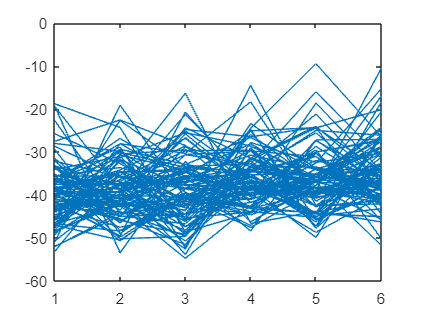

% 实线与浅色区域绘图
POT_color = [0.00,0.45,0.74];
Simple_color = [0.93,0.69,0.13];
Spatial_color = [0.85,0.33,0.10];
figure
A_ = mean(A,1);
fi = plot(20*log10(A'),'Color',POT_color);

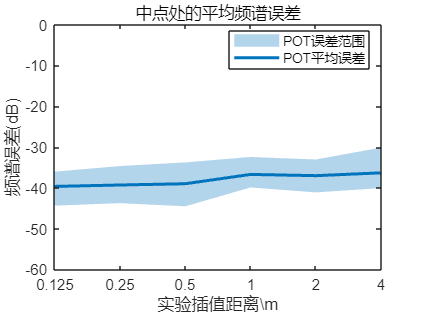


% 计算中值和第 25、75 个百分位数
    medianErrors = 20*log10(median(A,1));
    quantile25 = 20*log10(quantile(A, 0.25));
    quantile75 = 20*log10(quantile(A, 0.75));
    
    % 绘制阴影区域
    fill_between(1:1:6, quantile25, quantile75, POT_color, 'EdgeColor', 'none');
    hold on
    % 绘制中值误差曲线
    plot(1:6, medianErrors, 'k-', 'LineWidth', 2, 'Color',POT_color);
    hold on;
%plotErrorCurves(20.*log10(A),POT_color)
legend('POT误差范围', 'POT平均误差','Location', 'best');
xlabel('实验插值距离\\m');
xticklabels({'0.125', '0.25', '0.5', '1', '2', '4'});
ylabel('频谱误差(dB)');
title('中点处的平均频谱误差');
axis([1 6 -60 0]);
hold off

mean_range_draw(20*log10(SpError_list_W))
axis([0 1 -40 0])

% x_s = PCld_1.PointCloud(:,4);
% x_t = PCld_2.PointCloud(:,4);
% figure
% plot(abs(x_s/sum(x_s)));
% hold on
% plot(sum(T.T,2))
% 
% figure
% plot(abs(x_t/sum(x_t)));
% hold on
% plot(sum(T.T,1))
% 
% x_s_remain = abs(x_s/sum(x_s)) - sum(T.T,2);
% x_t_remain = abs(x_t/sum(x_t)) - sum(T.T,1)';
% 
% u = x_s_remain;
% v = x_t_remain;
% figure
% plot(x_s_remain)
% 
% figure
% plot(x_t_remain)

## 函数部分

function mean_range_draw(LIST)
POT_color = [0.00,0.45,0.74];
Simple_color = [0.93,0.69,0.13];
Spatial_color = [0.85,0.33,0.10];
% 
% plotErrorCurves(AbError_list_W(201:300,:),Simple_color)
% plotErrorCurves(AbError_list_W(101:200,:), Spatial_color)
% plotErrorCurves(AbError_list_W(1:100,:),POT_color)
figure
plotErrorCurves(LIST(201:300,:),Simple_color)
plotErrorCurves(LIST(1:100,:),POT_color)
legend('简单线性误差范围', '简单线性误差平均', 'POT误差范围', 'POT平均误差','Location', 'best');
xlabel('比例系数\kappa');
ylabel('Error');
title('参考点距离4m');
axis([0 1 -40 0]);
hold off
figure
plotErrorCurves(LIST(101:200,:),Spatial_color)
plotErrorCurves(LIST(1:100,:),POT_color)
legend('空间线性范围误差', '空间线性平均误差', 'POT范围误差', 'POT平均误差','Location', 'best');
xlabel('比例系数\kappa');
ylabel('Error');
title('参考点距离4m');
hold off
end    

function second_mic = mic_pair(first_mic, distance)
% 生成随机角度
theta = rand * 2 * pi; % 在 [0, 2*pi] 范围内生成随机角度
phi = rand * pi; % 在 [0, pi] 范围内生成随机角度

% 计算球面坐标系中的位置
x = distance * sin(phi) * cos(theta);
y = distance * sin(phi) * sin(theta);
z = distance * cos(phi);

% 将球面坐标系转换为直角坐标系
second_mic = first_mic + [x; y; z];
end

function PointCloud = SRIR2PCLD(SRIR, mic_position, order, fs)
% 从SRIR直接生成点云图

% 处理RIR数组
if iscell(SRIR)
    % 获取cell数组的大小
    %[num_cells, ~, Len] = size(rir);
    [num_cells, ~] = size(SRIR);
    % 初始化一个空矩阵来存储转换后的数据
    rir_length = [];

    % 循环遍历每个单元格
    for i = 1:num_cells
        Length = length(SRIR{i});
        rir_length = [rir_length; Length];
    end
    limit_len = min(rir_length);
    rir_data = zeros(num_cells,limit_len);

    for i = 1:num_cells
        rir_data(i,:) = SRIR{i}(1:limit_len);
    end
else
    rir_data = SRIR;%reshape(rir, [7, l]); % 转换矩阵尺寸为 [7, N]
end
% 处理RIR数组完毕

% 进行SDM
p.micLocs = mic_position';
p.fs = fs;
p.c = 345;
p.winLen = 0;
p.parFrames = 8192;
p.showArray = 0;
DOA = SDMPar(rir_data',p);
% SDM完成

% 处理并生成点云
% 生成一个逻辑向量，指示哪些值是非 NaN 值
valid_indices = ~isnan(DOA);

% 使用逻辑索引选取非 NaN 值
valid_DOA = DOA(valid_indices);
valid_DOA = reshape(valid_DOA, [], 3);

valid_amp_indice = valid_indices(:,1);
ori_amp = rir_data(7,:);
valid_amp = ori_amp(valid_amp_indice);

%尝试剔除幅值过小的点云
%幅值小于3e-4的可以被剔除%tips:用能量去筛选还是用幅值去筛选
% 计算直方图
[counts, edges] = histcounts(valid_amp.^2);
% 找到计数最多的组别的索引
[~, maxIndex] = max(counts);
% 获取具有最多计数的组别的范围
maxRange = [edges(maxIndex), edges(maxIndex + 1)];
pure_amp = [];
pure_DOA = [];
for i = 1:length(valid_amp)
    if abs(valid_amp(i)^2) >= abs(maxRange(2))/3*2
        pure_amp = [pure_amp, valid_amp(i)];
        pure_DOA = [pure_DOA; valid_DOA(i,:)];
    end
end
% scaleFactor = 2e3;
%pointcloud_plot(pure_amp, pure_DOA, scaleFactor)
%导出剔除后的点云图
PointCloud_export(pure_DOA, pure_amp', ['pure_square' order]);
PointCloud = load(['PointCloud_pure_square' order '.mat']);
end

function pointcloud_plot(amp, DOA, scaleFactor, Axis)
if nargin == 3
    Axis = [-60,60,-60,60,-30,30];
end
% 可以根据具体需求设计一个合适的映射关系，这里简单地将幅度信息乘以一个系数作为半径
% 将幅度信息映射到球的半径上
radius = abs(amp * scaleFactor); % scaleFactor 是一个缩放系数，用于调整球的大小
% 绘制散点图
%figure;
scatter3(DOA(:,1), DOA(:,2), DOA(:,3), radius', 'filled');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Three-dimensional scatter plot with amplitude-dependent spheres');
colorbar; % 添加颜色条，以显示幅度信息
hold on
% 读取STL文件
[vertices, ~, ~, ~] = stlread('D:\MATLAB\Matlab_HaHa\Degree_project\3D_model_file\zj425.stl');
room = triangulation(vertices.ConnectivityList, vertices.Points./1000);
% 显示STL模型
%trisurf(room, 'FaceColor', [0.8 0.8 0.8], 'FaceAlpha', 0.3, 'EdgeColor', 'none');
axis(Axis)
hold off;
end

function PointCloud_export(DOA, amp, str)
PointCloud = [DOA amp];
% 将数字转换为字符串
%ad = num2str(abs(mic_position(2,7)));

% 构造文件名
filename = ['PointCloud_', str,'.mat'];

% 保存数据到文件中
save(filename, 'PointCloud');
end

function h = PCld_rendering(loca, pres, reci_loca, fs, RT60)
fly_dist = sum((loca-repmat(reci_loca,length(loca),1)).^2,2).^0.5;
arr_time = fly_dist/345; %距离除以声速得到接收时的时间
[arr_time_sorted, sorted_order] = sort(arr_time);
t = zeros(ceil(RT60/1000*fs),1);
for k = 1:length(arr_time_sorted)
    t(floor(arr_time_sorted(k)*fs)) = t(floor(arr_time_sorted(k)*fs))+abs(pres(sorted_order(k)));
end
h = t;
end

function [r,z] = POT_interp(PCld_1, PCld_2, T, u, v, k_)

pure_T = T;
k = 1;%插入点的标号
%pure_T(abs(pure_T)<2e-3)=0;

T_ = pure_T;

for i = 1:length(u)
    if u(i) > 0
        if sum(pure_T(i,:)) == 0
            r(k) = (1-k_)*u(i);
            z(k,:) = PCld_1.PointCloud(i,1:3);
            k = k + 1;
        else
            T_(i,:) = T_(i,:) + (1-k_)*u(i)*pure_T(i,:)/sum(pure_T(i,:));
        end
    end
end
for j = 1:length(v)
    if v(j) > 0
        if sum(pure_T(:,j)) == 0
            r(k) = k_*v(j);
            z(k,:) = PCld_2.PointCloud(j,1:3);
            k = k + 1;
        else
            T_(:,j) = T_(:,j) + k_*v(j)*pure_T(:,j)/sum(pure_T(:,j));
        end
    end
end

[n,m] = size(T_);
for i = 1:n
    for j = 1:m
        if T_(i,j) > 0
            r(k) = T_(i,j);
            z(k,:) = (1-k_)*PCld_1.PointCloud(i,1:3)...
                + k_*PCld_2.PointCloud(j,1:3);
            k = k + 1;
        end
    end
end
end

function H_output_norm = Hann_filter(input, hann_length, fs, varargin)
% Parse optional input arguments
if nargin < 4 || isempty(varargin)
    plot_check = 0;
    Title = '';
else
    plot_check = varargin{1};
    if numel(varargin) > 1
        Title = varargin{2};
    else
        Title = '';
    end
end
% Apply Hann window
W_hann = hann(hann_length*fs);

% Convolve input with Hann window
H_output = conv(W_hann, input);

% Time vector for plotting
t_output = (0:length(H_output)-1) / fs;

% Normalize the output
H_output_norm = H_output / sum(H_output);

% Plot the output if plot_check is true
if plot_check == 1
    %     figure
    %     plot(t_output, H_output_norm);
    %     axis([0 max(t_output) 0 max(H_output_norm)])
    %     xlabel('Time (s)');
    %     ylabel('Normalized Amplitude');
    %     title(Title);

end
end
function error = spectral_error(signal1, signal2, fs)
% 计算信号的功率谱密度（PSD）
[pxx1, freq1] = pwelch(signal1, [], [], [], fs);
[pxx2, freq2] = pwelch(signal2, [], [], [], fs);

% 如果两个信号的频率轴不同，则进行插值使它们具有相同的频率轴
if ~isequal(freq1, freq2)
    freq_interp = min(freq1(1), freq2(1)):min(freq1(end), freq2(end));
    pxx1_interp = interp1(freq1, pxx1, freq_interp, 'linear', 'extrap');
    pxx2_interp = interp1(freq2, pxx2, freq_interp, 'linear', 'extrap');
else
    freq_interp = freq1;
    pxx1_interp = pxx1;
    pxx2_interp = pxx2;
end

% 计算频谱误差
error = (pxx1_interp - pxx2_interp).^2;
% figure
% plot(freq_interp,20*log10(error))
error = sum(error)/sum(pxx2_interp.^2);
end
function PCld = linearPCld_interp(PCld1,PCld2,k)
L1 = length(PCld1);
L2 = length(PCld2);
[~,order] = min([L1,L2]);
if order == 1
    PCld = (1-k)*PCld1 + k*PCld2(1:L1,:);
elseif order == 2
    PCld = (1-k)*PCld1(1:L2,:) + k*PCld2;
end

end

function h = linearTime_interp(h1,h2,k)
L1 = length(h1);
L2 = length(h2);
[~,order] = min([L1,L2]);
if order == 1
    h = abs((1-k)*h1 + k*h2(1:L1));
elseif order == 2
    h = abs((1-k)*h1(1:L2) + k*h2);
end

end

function rel_error = calculate_absolute_error(signal1, signal2)
% 计算两个信号的平方误差
% signal1 和 signal2 分别是两个信号的向量

% 确保两个信号长度相同
if length(signal1) ~= length(signal2)
    error('信号长度不一致');
end

% 计算平方误差
square_diff = (signal1 - signal2).^2;
rel_error = sum(square_diff)/sum(signal2.^2);
end

function plot_error_curves(Error_list1, Error_list2, Error_list3, Error_list4, title1, title2, title3, title4, K, epoch_num)
% Plot error curves for four error matrices with titles

x = repmat(K, epoch_num, 1);
% Plot first error matrix
figure;
plot(x', Error_list1(1:epoch_num,:)', 'Color','b','LineWidth',0.1);
hold on
plot(x', Error_list1(epoch_num+1: epoch_num*2,:)', 'Color','r','LineWidth',0.1);
hold on
plot(x', Error_list1(epoch_num*2+1: epoch_num*3,:)', 'Color','g','LineWidth',0.1);
title(title1);
xlabel('Sample');
ylabel('Error');
% fprintf('Sum of %s: %f\n', title1, sum(Error_list1, 2));
hold off

% Plot second error matrix
figure;
plot(x', Error_list2(1:epoch_num,:)', 'Color','b','LineWidth',0.1);
hold on
plot(x', Error_list2(epoch_num+1: epoch_num*2,:)', 'Color','r','LineWidth',0.1);
hold on
plot(x', Error_list2(epoch_num*2+1: epoch_num*3,:)', 'Color','g','LineWidth',0.1);
title(title2);
xlabel('Sample');
ylabel('Error');
% fprintf('Sum of %s: %f\n', title2, sum(Error_list2, 2));
hold off

% Plot third error matrix
figure;
plot(x', Error_list3(1:epoch_num,:)', 'Color','b','LineWidth',0.1);
hold on
plot(x', Error_list3(epoch_num+1: epoch_num*2,:)', 'Color','r','LineWidth',0.1);
hold on
plot(x', Error_list3(epoch_num*2+1: epoch_num*3,:)', 'Color','g','LineWidth',0.1);
title(title3);
xlabel('Sample');
ylabel('Error');
% fprintf('Sum of %s: %f\n', title3, sum(Error_list3, 2));
hold off

% Plot fourth error matrix
figure;
plot(x', Error_list4(1:epoch_num,:)', '--','Color','b','LineWidth',0.1);
xlabel('Sample');
ylabel('Error');
title('POT');
axis([0 1 0 3])
figure;
plot(x', Error_list4(epoch_num+1: epoch_num*2,:)','--','Color','r','LineWidth',0.1);
xlabel('Sample');
ylabel('Error');
title('Linear');
axis([0 1 0 3])
figure
plot(x', Error_list4(epoch_num*2+1: epoch_num*3,:)', '--','Color','g','LineWidth',0.1);
title('TimeLinear');
xlabel('Sample');
ylabel('Error');
axis([0 1 0 3])
% fprintf('Sum of %s: %f\n', title4, sum(Error_list4, 2));
end
function plotMethodPerformance(VOTE, numEnvironments)
    % VOTE: N*6 矩阵，记录了三种方法在6种不同环境下的性能，其中1,2,3代表三种方法的性能表现最佳
    % numEnvironments: 实验环境的数量
    
    % 计算每种方法在每个实验环境中的数量
    methodCounts = zeros(3, numEnvironments);
    for i = 1:numEnvironments
        for j = 1:3
            methodCounts(j, i) = sum(VOTE(:, i) == j);
        end
    end
    
    % 确保每种方法的数量总和为 N
    totalCounts = sum(methodCounts, 1);
    totalCountsMatrix = repmat(totalCounts, 3, 1);
    methodCounts = methodCounts ./ totalCountsMatrix * size(VOTE, 1);
    
    % 绘制柱状图
    colors = ['r', 'b', 'g'];  % 分别表示三种方法的颜色
    figure;
    hold on;
    bar(methodCounts','stacked');

    
    % 设置横坐标的标签
    xticks(1:numEnvironments);  % 设置 x 轴刻度位置
    xticklabels({'0.125', '0.25', '0.5', '1', '2', '4'});  % 设置 x 轴刻度标签
    yticks(100:200:1900);
    % 添加图例和标签
    legend('POT', '空间线性', '简单线性', 'Location', 'best');
    xlabel('距离\\m');
    ylabel('次数');
    title('不同参考点距离下算法性能最优次数');
    
    hold off;
end
function plotErrorCurves(errors,color)
    % errors: 100*19 矩阵，每一行代表一次实验中在不同插值比例系数下的误差曲线
    
    numExperiments = size(errors, 1);
    x = 0.05:0.05:0.95;  % 插值比例系数
    
    % 计算中值和第 25、75 个百分位数
    medianErrors = median(errors);
    quantile25 = quantile(errors, 0.25);
    quantile75 = quantile(errors, 0.75);
    
    % 绘制阴影区域
    fill_between(x, quantile25, quantile75, color, 'EdgeColor', 'none');
    hold on
    % 绘制中值误差曲线
    plot(x, medianErrors, 'k-', 'LineWidth', 2, 'Color',color);
    hold on;
    % 添加图例和标签
%     legend('Median Error', '25th-75th Percentile Range', 'Location', 'best');
    xlabel('Interpolation Coefficient');
    ylabel('Error');
    title('Error Curves with Median and Percentile Range');
    axis([0 1 0 1])
    hold on;
end

% 辅助函数，用于绘制阴影区域
function fill_between(x, y1, y2, color, varargin)
    % x: x 坐标
    % y1, y2: y 坐标的上下限
    % color: 阴影区域的颜色
    % varargin: 其他参数传递给 fill 函数
    
    x = x(:)';
    y1 = y1(:)';
    y2 = y2(:)';
    
    fill([x, fliplr(x)], [y1, fliplr(y2)], color, varargin{:},'FaceAlpha',0.3);
end